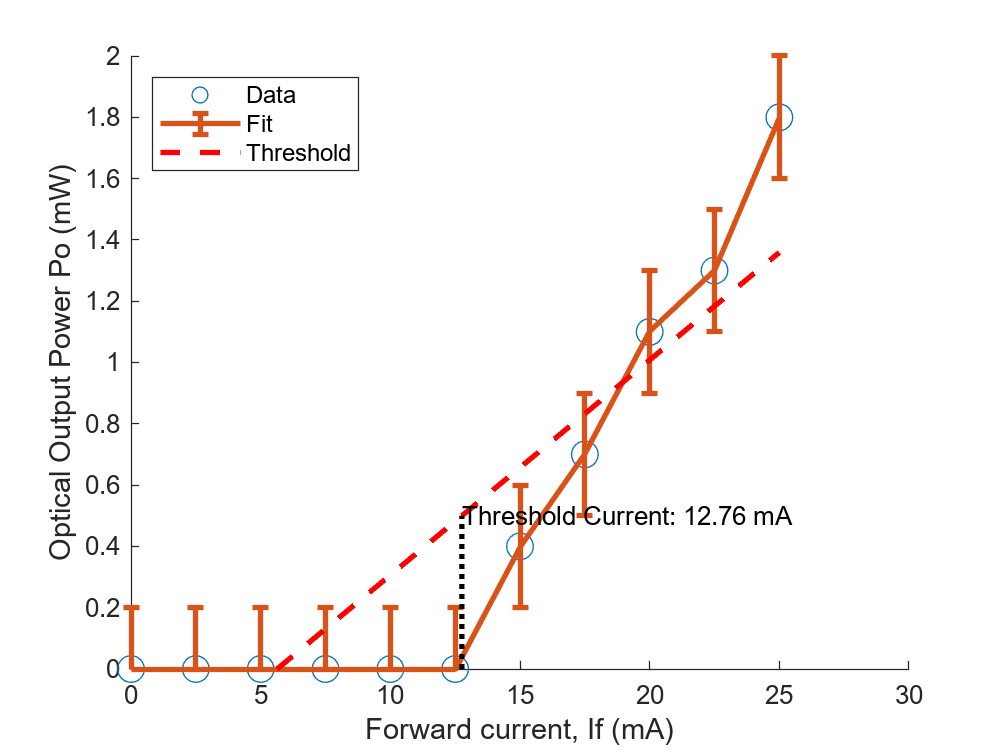

clc;
clear;
clear all;


filename = 'LaserDiodeC.xlsx';
[z_numeric, ~, ~,] = xlsread("LaserDiodeC.xlsx");

z = z_numeric;

%A1 plot

% Define data
x = [0,2.5,5,7.5,10,12.5,15,17.5,20,22.5,25];
y = [0,0,0,0,0,0,0.4,0.7,1.1,1.3,1.8];
err = 0.2 * ones(size(y));

% Plot the data
figure(1)
scatter(x, y, 100)
hold on
errorbar(x, y, err, 'LineWidth', 2)

% Fit a curve to the data 
p = polyfit(x, y, 1);
xfit = linspace(0, 25, 100);
yfit = polyval(p, xfit);
plot(xfit, yfit, 'r--', 'LineWidth', 2)

% Find the threshold current (intersection with a certain power level)
threshold_power = 0.5; 
threshold_current = (threshold_power - p(2)) / p(1);
plot([threshold_current, threshold_current], [0, threshold_power], 'k:', 'LineWidth', 2)

% Plot the value of the threshold current
text(threshold_current, threshold_power, sprintf('Threshold Current: %.2f mA', threshold_current), 'HorizontalAlignment', 'left')

hold off
xlim([0, 30])
ylim([0, 2])
xlabel('Forward current, If (mA)')
ylabel('Optical Output Power Po (mW)')
legend('Data', 'Fit', 'Threshold', 'Location', 'NorthWest') 


%A2 find slope
p = polyfit (x,y,1);
p

p =     0.0702   -0.3955



%A3
OpticalPower = 7;
ConsumedInputPower = 1.8;
WallPlugEfc = OpticalPower / ConsumedInputPower

WallPlugEfc = 3.8889


%A4 exteneral differential quantum efficieny ([delP / delI) * (qlam/he)]
q = 1.602*10^-19;
lambda = 637*10^-9; %from data sheet
h = 6.62*10^-34; %plancks constant
c = 2.98*10^8; %speed of light
ExteneralDifferentialQuantumEfficieny = p(1,1) * ((q*lambda)/(h*c))

ExteneralDifferentialQuantumEfficieny = 0.0363


%A5 calculate no. of laser photons produced by one elctron-hole pair
% Constants
h = 6.626e-34; % Planck's constant (Joule second)
c = 3.0e8; % Speed of light (m/s)
q = 1.602e-19; % Elementary charge (Coulombs)
lambda = 637e-9; % Wavelength (m) - from datasheet

% Calculate the energy of a single photon
E_photon = h * c / lambda; % Energy of a single photon (Joules)

% Conversion factor from photodiode measurement (100mV/mW)
conversion_factor = 100e-3; % (V/mW)

% Power measured by the photodiode 
power_measured = 1.8; % mW

% Calculate the number of photons per second
photons_per_second = power_measured / conversion_factor * (1 / E_photon);

% Current flowing into the junction 
threshold_current = 12.53e-3; 

% Calculate the number of electrons per second flowing into the junction
electrons_per_second = threshold_current / q; % Number of electrons per second

% Calculate the number of laser photons produced by one electron-hole pair
photon_per_electron_hole_pair = photons_per_second / electrons_per_second;

disp(['Number of laser photons produced by one electron-hole pair: ', num2str(photon_per_electron_hole_pair)]);

Number of laser photons produced by one electron-hole pair: 737.4808


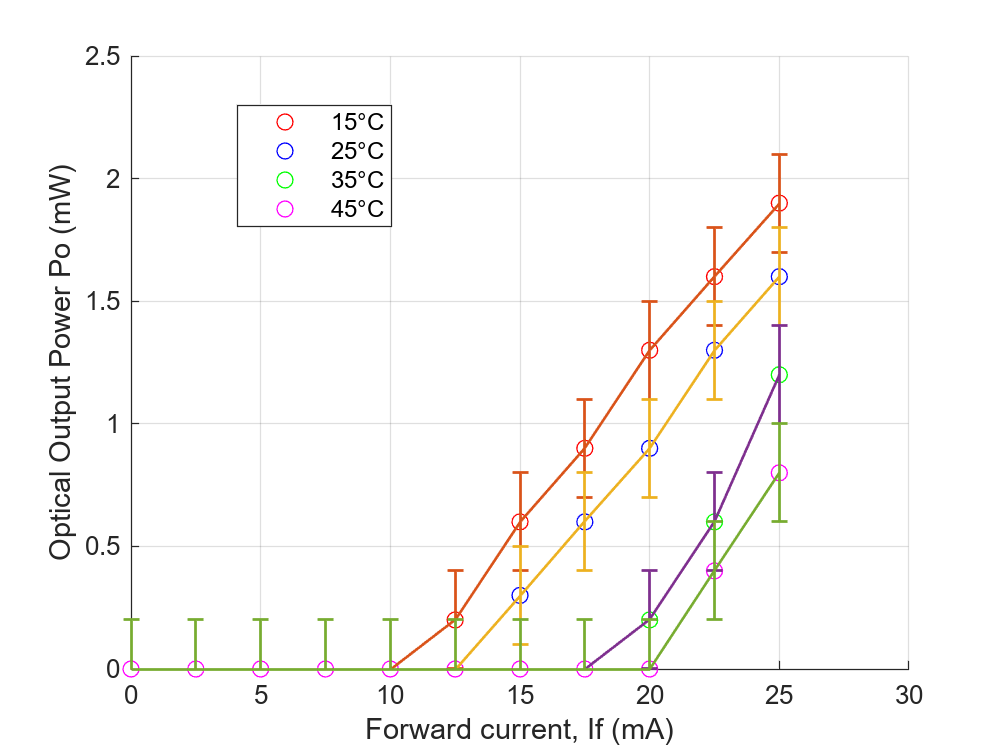





%B1
% Define data for different temperatures
y1 = [0,0,0,0,0,0.2,0.6,0.9,1.3,1.6,1.9];
y2 = [0,0,0,0,0,0,0.3,0.6,0.9,1.3,1.6];
y3 = [0,0,0,0,0,0,0,0,0.2,0.6,1.2];
y4 = [0,0,0,0,0,0,0,0,0,0.4,0.8];

% Plotting
figure(2)
hold on
scatter(x, y1, 'r')
scatter(x, y2, 'b')
scatter(x, y3, 'g')
scatter(x, y4, 'magenta')
plot(x, y1, 'r', x, y2, 'b--', x, y3, 'g:', x, y4, 'magenta-.')
errorbar(x, y1, err, 'linewidth', 1)
errorbar(x, y2, err, 'linewidth', 1)
errorbar(x, y3, err, 'linewidth', 1)
errorbar(x, y4, err, 'linewidth', 1)
hold off
xlim([0, 30])
ylim([0, 2.5])
grid on
xlabel('Forward current, If (mA)')
ylabel('Optical Output Power Po (mW)')
legend('15°C', '25°C', '35°C', '45°C')

legend("Position", [0.23738,0.69857,0.15256,0.16142])


% Calculate and print threshold currents for each temperature
threshold_temps = zeros(1, 4); % Array to store threshold currents for each temperature

for i = 1:4
    % Fit a linear curve to the data
    p = polyfit(x, eval(['y', num2str(i)]), 1);
    
    % Find the threshold current (intersection with a certain power level)
    threshold_power = 0.5; 
    threshold_current = (threshold_power - p(2)) / p(1);
    threshold_temps(i) = threshold_current;
    
    % Print threshold current for each temperature
    disp(['Threshold Current at ', num2str((i - 1) * 10 + 15), '°C: ', num2str(threshold_current), ' mA']);
end

Threshold Current at 15°C: 11.3739 mA
Threshold Current at 25°C: 13.6494 mA
Threshold Current at 35°C: 22.2222 mA
Threshold Current at 45°C: 31.6964 mA


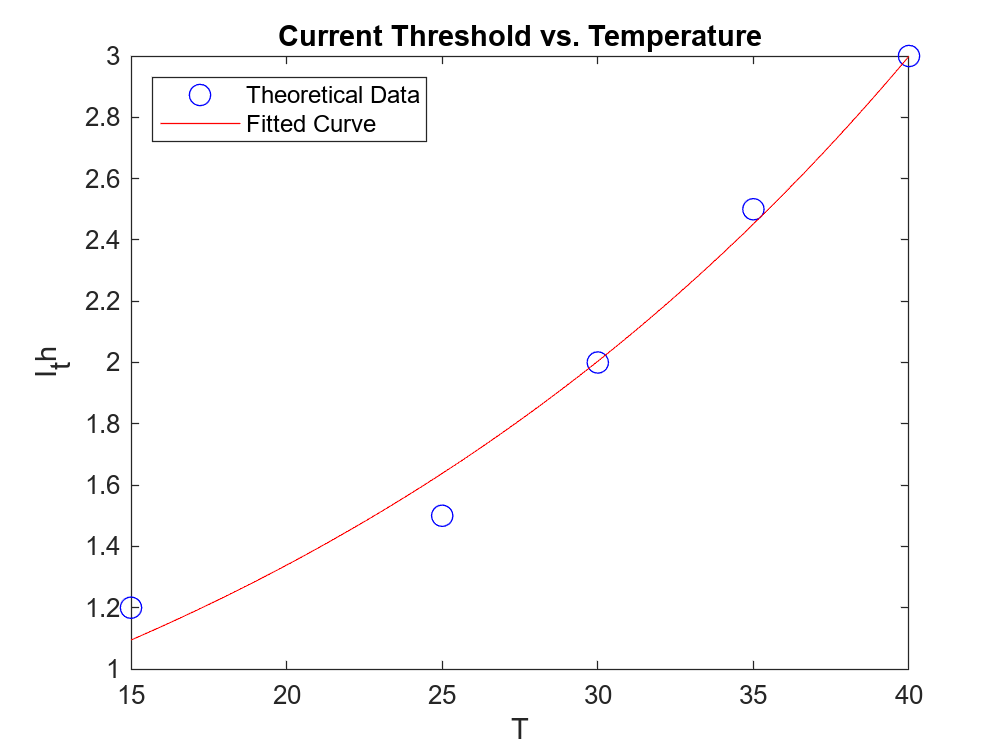





%B2
% data 
T = [15, 25, 30, 35, 40]; % Temperature (in Kelvin)
I_th = [1.2, 1.5, 2.0, 2.5, 3.0]; % Current threshold (in amps)

% Plot the data
figure;
plot(T, I_th, 'bo', 'MarkerSize', 8);
xlabel('Temperature (K)');
ylabel('Current Threshold (A)');
title('Current Threshold vs. Temperature');

% Fit the data to the equation I_th = I_0 * exp(T/T0)
f = fittype('I_0 * exp(T/T0)', 'independent', 'T', 'dependent', 'I_th');
opts = fitoptions(f);
opts.StartPoint = [1, 100]; % Initial guess for fitting parameters [I_0, T_0]
opts.Lower = [0, 0]; % Lower bounds for fitting parameters [I_0, T_0]
opts.Upper = [Inf, Inf]; % Upper bounds for fitting parameters [I_0, T_0]
[fitted_curve, gof] = fit(T', I_th', f, opts);

% Plot the fitted curve
hold on;
plot(fitted_curve, 'r');
legend('Theoretical Data', 'Fitted Curve', 'Location', 'northwest');
hold off 


% Extract the characteristic temperature T0
T0 = fitted_curve.T0;

% Display T0
fprintf('Characteristic Temperature (T0): %.2f K\n', T0);

Characteristic Temperature (T0): 24.80 K


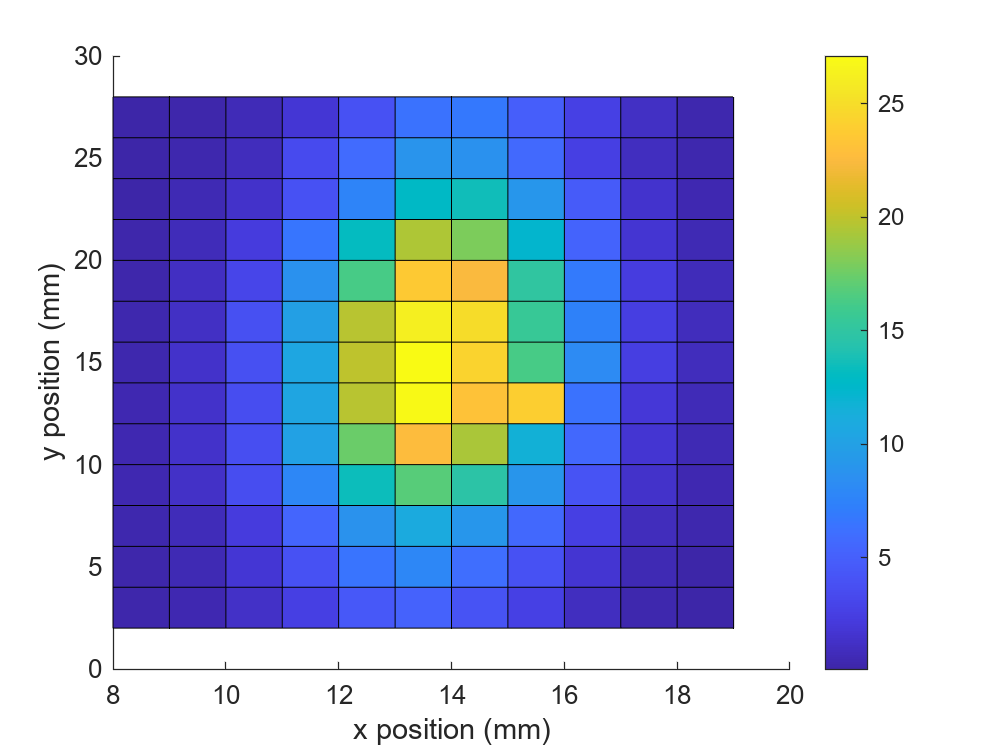





%C
figure (3)

x1 = [8,9,10,11,12,13,14,15,16,17,18,19];
y5 = [2,4,6,8,10,12,14,16,18,20,22,24,26,28];
surf(x1,y5,z)
colorbar();
view(0,90)
grid off
xlabel('x position (mm)')
ylabel('y position (mm)')
zlabel('Outut Power (mW)')